# 2D predator-prey model with limit cycle

### Based on

[1] Van der Hoff Q, Greeff JC, Kloppers PH. Numerical investigation into the existence of limit cycles in two-dimensional predator-prey systems. S Afr J Sci. 2013;109(5/6), Art.#1143, 6 pages. http://dx.doi.org/10.1590/sajs.2013/1143

The dynamic equations are as follows:


$$\dot x = r \, x \, \Big(1 - \frac{x}{K}\Big) - y \, \Big( \frac{a x}{b + x} \Big)$$



$$\dot y = - c \, y + D \, y \, \Big( \frac{a x}{b + x} \Big)$$


- $K$is the carrying capacity of the environment w.r.t. the prey ($x$)

- $r$ is the intrinsic growth rate of prey ($x$) in the absence of predators

- $c$ is the death rate of the predator ($y$) in the absence of prey, while $D$ is the rate of the conversion of consumed prey to predator.

- The term $\frac{a x}{b + x}$ represents a Holling Type II functional response, describing the expected number of prey devoured by a predator per unit of time.

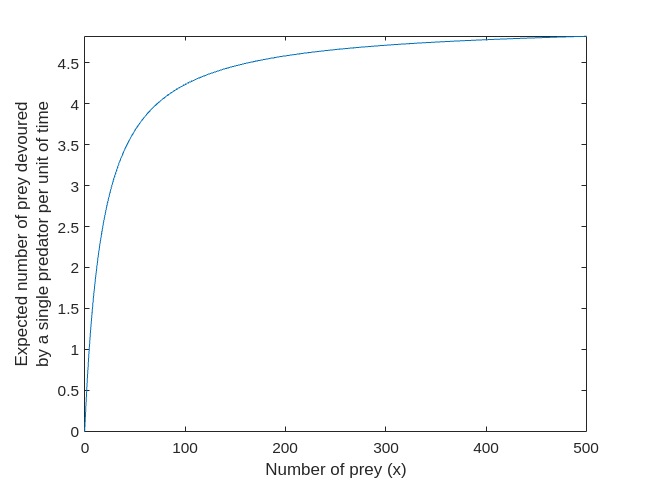

a = 5;
b = 18;
fplot(@(x) a*x./(b+x),[0 500])
xlabel('Number of prey (x)')
ylabel({'Expected number of prey devoured' 'by a single predator per unit of time'})

Parameters and assumptions

syms r a b D c K real
assumeAlso([r a b c D K] > 0)

State variables

syms x y real

State equations in the form $(\dot x,\dot y) = f(x,y)$

f = [
    r*x*(1 - x/K) - y*(a*x)/(b+x)
    -c*y + D*y*(a*x)/(b+x)
    ]

$$f = \left(\begin{array}{c} -r\,x\,\left(\frac{x}{K}-1\right)-\frac{a\,x\,y}{b+x}\\ \frac{\text{D}\,a\,x\,y}{b+x}-c\,y \end{array}\right)$$

Find the equilibrium but only INSIDE the positive orthant.

assumeAlso([x y] > 0) % Only the positive orthant is interesting
sol = solve(f,[x;y],'ReturnConditions',true)

sol = struct with fields:
             x: -(b*c)/(c - D*a)
             y: -(c*r*D*b^2 - K*a*r*D^2*b + K*c*r*D*b)/(K*D^2*a^2 - 2*K*D*a*c + K*c^2)
    parameters: [1×0 sym]
    conditions: c < D*a & (D^2*a^2 - 2*D*a*c + c^2)*(K*c + b*c - D*K*a) < 0

The equilibrium point is denoted by $P$

P = simplify([sol.x ; sol.y])

$$P = \left(\begin{array}{c} -\frac{b\,c}{c-\text{D}\,a}\\ -\frac{\text{D}\,b\,r\,\left(K\,c+b\,c-\text{D}\,K\,a\right)}{K\,{\left(c-\text{D}\,a\right)}^{2}} \end{array}\right)$$

Compute the Jacobian matrix of $f(x,y)$ to obtain the state transition matrix  

J = jacobian(f,[x;y])

$$J = \left(\begin{array}{cc} \frac{a\,x\,y}{{\left(b+x\right)}^{2}}-\frac{a\,y}{b+x}-\frac{r\,x}{K}-r\,\left(\frac{x}{K}-1\right) & -\frac{a\,x}{b+x}\\ \frac{\text{D}\,a\,y}{b+x}-\frac{\text{D}\,a\,x\,y}{{\left(b+x\right)}^{2}} & \frac{\text{D}\,a\,x}{b+x}-c \end{array}\right)$$

The Jacobian matrix is evaluated symbolically in the equilibrium point.

A = simplify(subs(J,[x;y],P))

$$A = \left(\begin{array}{cc} \frac{c\,r\,\left(K\,c+b\,c-\text{D}\,K\,a+\text{D}\,a\,b\right)}{\text{D}\,K\,a\,\left(c-\text{D}\,a\right)} & -\frac{c}{\text{D}}\\ -\frac{r\,\left(K\,c+b\,c-\text{D}\,K\,a\right)}{K\,a} & 0 \end{array}\right)$$

det(A)

$$ans = -\frac{c\,r\,\left(K\,c+b\,c-\text{D}\,K\,a\right)}{\text{D}\,K\,a}$$

sol = solve(det(A),K,'ReturnConditions',true)

sol = struct with fields:
             K: -(b*c)/(c - D*a)
    parameters: [1×0 sym]
    conditions: c < D*a

The determinant of $A$ is positive if $K > \frac{bc}{aD - c}$:

simplify(subs(det(A),K,b*c/(D*a - c)+1))

$$ans = \frac{c\,r\,{\left(c-\text{D}\,a\right)}^{2}}{\text{D}\,a\,\left(\text{D}\,a-c+b\,c\right)}$$

When the determinant is positive, the sign of the trace of A will determine whether the equilibrium is a sink or a source.

(Pozitív A determináns esetén mátrix nyomának előjele határozza meg, hogy az egyensúlyi pont vonzzó-e vagy taszító.)

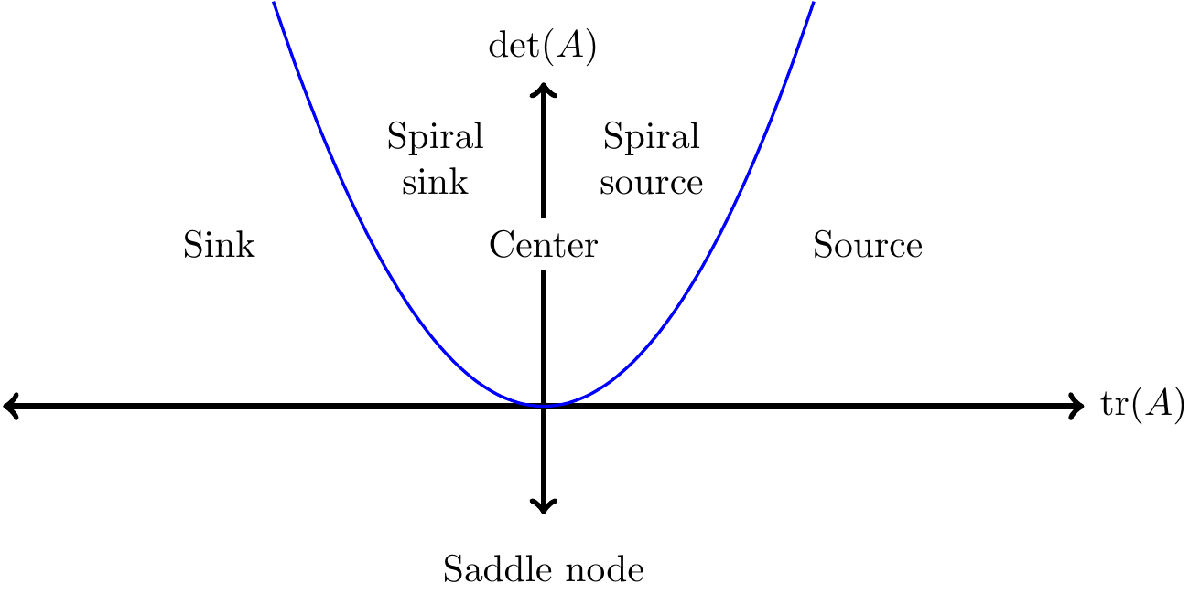

Tr = trace(A)

$$Tr = \frac{c\,r\,\left(K\,c+b\,c-\text{D}\,K\,a+\text{D}\,a\,b\right)}{\text{D}\,K\,a\,\left(c-\text{D}\,a\right)}$$

sol = solve(Tr,K,'ReturnConditions',true)

sol = struct with fields:
             K: -(b*c + D*a*b)/(c - D*a)
    parameters: [1×0 sym]
    conditions: c < D*a

So the Hopf bifurcation point is at $K = \frac{b(aD + c)}{aD - c}$.